a = 0 

a = 0

b = 7

b = 7

x = linspace(a,b,500)

x =          0    0.0140    0.0281    0.0421    0.0561    0.0701    0.0842    0.0982    0.1122    0.1263    0.1403    0.1543    0.1683    0.1824    0.1964    0.2104    0.2244    0.2385    0.2525    0.2665    0.2806    0.2946    0.3086    0.3226    0.3367    0.3507    0.3647    0.3788    0.3928    0.4068    0.4208    0.4349    0.4489    0.4629    0.4770    0.4910    0.5050    0.5190    0.5331    0.5471    0.5611    0.5752    0.5892    0.6032    0.6172    0.6313    0.6453    0.6593    0.6733    0.6874


h = 0.001 

h = 1.0000e-03

iter=1000 

iter = 1000

eps=0.001

eps = 1.0000e-03

f=@(x)1+(1+sin(x)-cos(x)).^(2)-(sin(2*x)-cos(2*x)-0.2).^(2)

f = function_handle with value:
    @(x)1+(1+sin(x)-cos(x)).^(2)-(sin(2*x)-cos(2*x)-0.2).^(2)


y=f(x)

y =    -0.4400   -0.3723   -0.3041   -0.2356   -0.1668   -0.0980   -0.0293    0.0391    0.1070    0.1744    0.2409    0.3066    0.3712    0.4346    0.4967    0.5574    0.6165    0.6739    0.7296    0.7833    0.8351    0.8849    0.9325    0.9779    1.0211    1.0620    1.1006    1.1368    1.1707    1.2022    1.2313    1.2580    1.2824    1.3045    1.3243    1.3418    1.3572    1.3705    1.3817    1.3910    1.3984    1.4040    1.4079    1.4103    1.4113    1.4109    1.4093    1.4067    1.4032    1.3989


plot(x,f(x),x,0*x,':') 
grid on
xlabel('x')
ylabel('y')
hold on
ymin=min(y)

ymin = -1.5147

ymax=max(y)

ymax = 6.3233

if ymin<0 
    ymin=1.1*ymin
else 
    ymin=0.9*ymin
end

ymin = -1.6661

if ymax>0 
    ymax=1.1*ymax
else 
    ymax=0.9*ymax
end

ymax = 6.9557

axis([a,b,ymin,ymax])
z = ginput(2)

z =     2.5074    4.4880
    4.3508   -0.2862


z1=z(1,1)

z1 = 2.5074

z2=z(2,1)

z2 = 4.3508

f1 = f(z1)

f1 = 4.6413

f2=f(z2)

f2 = -0.2926

z=(z1+z2)/2 

z = 3.4291

y=f(z)

y = 3.5616

P = plot(z1,0,'*',z2,0,'*',z,0,'o')

P =   3×1 Line array:

  Line
  Line
  Line


if f1*f2>0 
    'Точки находятся по одну сторону от оси x'
end
for i=1:iter
l=i
z=(z1+z2)/2; y=f(z)
delete(P);
P=plot(z1,0,'*',z2,0,'*',z,0,'o')
if y*f1<0
z2=z
else 
    z1=z
end
if abs(f(z))<eps
break
end
end

l = 1

y = 3.5616

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.4291

l = 2

y = 1.5843

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.8900

l = 3

y = 0.3129

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 4.1204

l = 4

y = -0.1009

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 4.2356

l = 5

y = 0.0803

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 4.1780

l = 6

y = -0.0171

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 4.2068

l = 7

y = 0.0300

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 4.1924

l = 8

y = 0.0060

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 4.1996

l = 9

y = -0.0056

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 4.2032

l = 10

y = 1.8748e-04

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 4.2014

l

l = 10

disp("Найденный корень ")

Найденный корень 


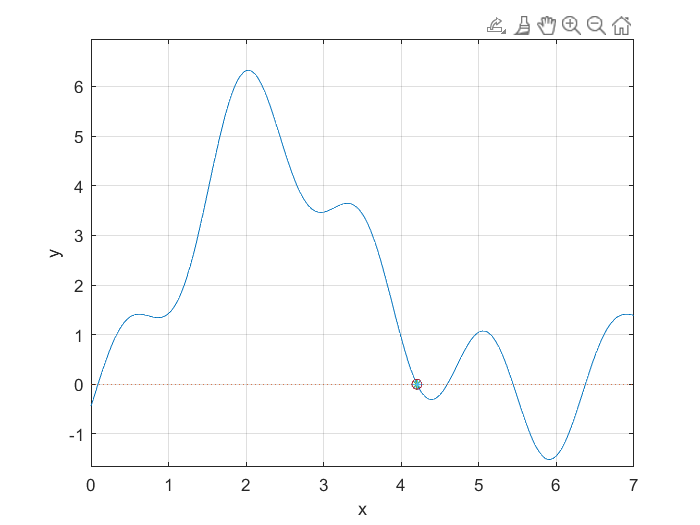

z = 4.2014

z